# Pb1

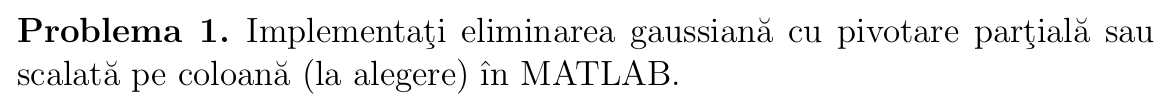

    Pivotarea parțială alege ca pivot elementul cu cea mai mare valoare absolută de pe coloana curentă, oferind o stabilitate numerică rezonabilă în majoritatea cazurilor. 

    Pivotarea scalată, normalizează fiecare element al coloanei față de maximul liniei sale, fiind mai robustă când apar diferențe mari de ordin între coeficienți. Astfel, metoda scalată previne instabilitățile numerice în sisteme dezechilibrate.

## Eliminare Gauss cu pivotare partiala

pivotare partiala = se interschimba randuri

function x = gauss_pivot_partial(A, b)
% INPUT:
%   A - matricea coeficienților (n x n)
%   b - vectorul termenilor liberi (n x 1)
%
% OUTPUT:
%   x - soluția sistemului Ax = b
%
% Metoda: Eliminare Gauss cu pivotare partiala (pe coloana)

    [n, ~] = size(A);
    Ab = [A, b]; % Matrice extinsă

    for i = 1:n-1
        % Gasire pivot (valoare maxima absoluta pe coloana i, de la linia i in jos)
        [~, p] = max(abs(Ab(i:n, i)));
        p = p + i - 1;

        if Ab(p, i) == 0
            error('Sistemul nu are soluție unică.');
        end

        % Schimbare de linii, dacă e cazul
        if p ~= i
            Ab([i, p], :) = Ab([p, i], :);
        end

        % Eliminare
        for j = i+1:n
            m = Ab(j, i) / Ab(i, i);
            Ab(j, i:end) = Ab(j, i:end) - m * Ab(i, i:end);
        end
    end

    if Ab(n, n) == 0
        error('Sistemul nu are soluție unică.');
    end

    % Substitutie inversa
    x = zeros(n, 1);
    for i = n:-1:1
        x(i) = (Ab(i, end) - Ab(i, i+1:n) * x(i+1:n)) / Ab(i, i);
    end
end

##  Eliminare Gauss cu pivotare **scalata pe coloana**

function x = gauss_pivot_scalat(A, b)
% INPUT:
%   A - matricea coeficienților (n x n)
%   b - vectorul termenilor liberi (n x 1)
%
% OUTPUT:
%   x - solutia sistemului Ax = b
%
% Metoda: Eliminare Gauss cu pivotare scalata pe coloana
% (aleg pivot in functie de valoarea relativa la scara liniei)

    [n, ~] = size(A);
    Ab = [A, b]; % Matrice extinsă

    % Vector de scalare: maximul absolut pe fiecare linie
    s = max(abs(A), [], 2);

    for i = 1:n-1
        % Calcul pivot scalat: max |a_ij| / s_i
        ratios = abs(Ab(i:n, i)) ./ s(i:n);
        [~, p] = max(ratios);
        p = p + i - 1;

        if Ab(p, i) == 0
            error('Sistemul nu are soluție unică.');
        end

        % Schimbare de linii, dacă e cazul
        if p ~= i
            Ab([i, p], :) = Ab([p, i], :);
            s([i, p]) = s([p, i]); % swap și în vectorul de scalare
        end

        % Eliminare
        for j = i+1:n
            m = Ab(j, i) / Ab(i, i);
            Ab(j, i:end) = Ab(j, i:end) - m * Ab(i, i:end);
        end
    end

    if Ab(n, n) == 0
        error('Sistemul nu are soluție unică.');
    end

    % Substituție inversă
    x = zeros(n, 1);
    for i = n:-1:1
        x(i) = (Ab(i, end) - Ab(i, i+1:n) * x(i+1:n)) / Ab(i, i);
    end
end

A = [2 -1 1; 
    3 3 9; 
    3 3 5];
b = [2; -1; 4];

% Testare pivotare partiala
x_partial = gauss_pivot_partial(A, b);
disp('Solutie - pivotare partiala:');

Solutie - pivotare partiala:


disp(x_partial);

    2.2222
    1.1944
   -1.2500




% Testare pivotare scalata
x_scalat = gauss_pivot_scalat(A, b);
disp('Solutie - pivotare scalata:');

Solutie - pivotare scalata:


disp(x_scalat);

    2.2222
    1.1944
   -1.2500

